## Introduction to working with the xATLy toolbox

The xATLy toolbox is a set of classes and functions implemented to be integrated into MathWorks MATLAB® environments. The toolbox facilitates the reading, visualization, and processing of ICESat-2 ATL03 and ATL08 in HDF5 format with the end goal of generating customized along-track terrain and canopy height data sets. 

Motivated by the need to build synergies between ATL03 and ATL08 data in deriving vegetation height estimates, the xATLy toolbox implements three main class objects in an object-oriented design: 

- *Atl03*, an ATL03 granule class which offers an interface for accessing photon level 3D data from HDF5 files;

- *Atl08*, an ATL08 granule object that offers access to a variety of ATL08 segment level attributes, canopy and terrain height metrics and signal photon level classifications, and 

- *gtrack*, a ground track object – one of six ground tracks in an ATL03/ATL08 granule. 

The gtrack object is modeled as a composition to bind its relationship with matching ATL03 and ATL08 granule objects. Methods for the gtrack object usually output data in table format, which include raw, classified and normalized ATL03 points. Other outputs include auxilliary data e.g. ATL08 segment polygon in shapefile or KML format.

The follwing sections demonstrates features of the xATLy toolbox including:

- Defining Atl03 and Atl08 objects

- Defining ground track object for data access

- Exploring and reading data and attributes from defined ground track

- Displaying raw and classified ATL03 point clouds for a ground track

- Generating auxilliary Reference ground track (RGT) and ATL08 segment vector data

- Saving retrieved point cloud data

- Concluding remarks

### Define Atl03 and Atl08 objects

Access to ATL03 and ATL08 data is established through respective `Atl03` and `Atl08` objects as illustrated below. Two filepaths are provided, one for the ATL03 and othe other for the matching ATL08 data.

atl03path = '.\data\ATL03_20190603025340_10050314_002_01.h5'; % ATL03 filepath
atl08path = '.\data\ATL08_20190603025340_10050314_002_01.h5'; % ATL08 filepath

% creates Atl03 and Atl08 objects
a3 = Atl03(atl03path);
a8 = Atl08(atl08path);

Display basic object properties using MATLAB disp function. 

% ATL03 - basic attributes
disp(a3) 

  Atl03 with properties:

        filepath: '.\data\ATL03_20190603025340_10050314_002_01.h5'
     producttype: 'ATL03'
        orbitnum: 3980
        cyclenum: 3
       sc_orient: 0
    groundtracks: {'gt1l'  'gt1r'  'gt2l'  'gt2r'  'gt3l'  'gt3r'}
    beamsequence: {'Strong'  'Weak'  'Strong'  'Weak'  'Strong'  'Weak'}



For a slightly detailed display of granule properties one can use the `showinfo` method for both the `Atl03` and `Atl08` objects. The ATL03/ and ATL08 products have numerous attributes. The `showinfo` method only outputs a few attributes an overview of dataset as shown below.

a3.showinfo() % detailed attributes/values

 <--------------------------- Dataset Info ------------------------->
                                                         
   Granule ID: ATL03_20190603025340_10050314_002_01.h5
   Version ID: 002
   Orbit/Cycle number: 3980/3
   Spacecraft orientation: 0 [Backward] 
                                                         
   Track IDs: | gt1l | gt1r | gt2l | gt2r | gt3l | gt3r | 
   Beam sequence: | Strong | Weak | Strong | Weak | Strong | Weak | 
   Number points: | 77918 | 18455 | 57574 | 20583 | 85455 | 19403 | 
                                                         
   Min/Max Lat/Lon: [-13.7157 23.8022] [-13.7155 23.8626]
   Approx. Range(km): 3.25
                                                         
 <--------------------------- End of Info ------------------------->


% ATL08
disp(a8)

  Atl08 with properties:

        filepath: '.\data\ATL08_20190603025340_10050314_002_01.h5'
     producttype: 'ATL08'
        orbitnum: 3980
        cyclenum: 3
       sc_orient: 0
    groundtracks: {'gt1l'  'gt1r'  'gt2l'  'gt2r'  'gt3l'  'gt3r'}
    beamsequence: {'Strong'  'Weak'  'Strong'  'Weak'  'Strong'  'Weak'}



a8.showinfo()

 <--------------------------- Dataset Info ------------------------->
                                                         
   Granule ID: ATL08_20190603025340_10050314_002_01.h5
   Version ID: 002
   Orbit/Cycle number: 3980/3
   Spacecraft orientation: 0 [Backward] 
                                                         
   Track IDs: | gt1l | gt1r | gt2l | gt2r | gt3l | gt3r | 
   Beam sequence: | Strong | Weak | Strong | Weak | Strong | Weak | 
   No. segments: | 986 | 449 | 985 | 304 | 986 | 320 | 
   No. canopy pts: | 41884 | 4201 | 41601 | 4741 | 47070 | 3705 | 
   No. top.canopy pts: | 13108 | 646 | 13349 | 879 | 15155 | 581 | 
   No. terrain pts: | 153367 | 22768 | 94378 | 14249 | 140335 | 16016 | 
                                                         
   Min/max Lat/Lon: [-13.9793, 23.8290] [-13.9768, 23.8893]
   Approx. distance: 3.51 km
   Min/max canopy height (m): [0.5, 38.2]
   Min/max terrain height (m): [1031.9, 1155.8]
                                        

Notice the matching orbit number (orbitnum), cycle number (cyclenum) between the two objects. This is a critical requirement to ensure both datasets represent indentical ground tracks. As a cosequence, ground tracks (groundtracks) and beam sequence (beamsequence) are identical too. However, there are cases when some tracks are not processed in the ATL08 product, maybe due to data corruption. In such as case, some ATL03 tracks might not have corresponding ATL08 tracks. 

The spacecraft determines the sequence of strong and week beams. In this case the spacecraft orietation is backward (sc_orient = 0), strong beams lead weak beams in each pair.

### Define a gtrack object

In the xATLy toolbox, calculations are performed at ground track level. A gtrack object has a relationship to matching Atl03 and Atl08 objects. This implementation is motivated mainly by the need to a build synergy between the two products for vegetation applications. The code below initializes a gtrack object for the 'gt1l' track, which is strong beam as shown by the properties above. 

gt = gtrack('gt1l',a3,a8);
disp(gt)

  gtrack with properties:

     gtrackid: 'gt1l'
        atl03: [1×1 Atl03]
        atl08: [1×1 Atl08]
    beamlevel: 'Strong'



From the output, you can see that this ground track object has atl03 and atl08 properties, which establishes the relationship. With the arrangement, one can access ATL03 related attributes through the atl03 object. Likewise one can access ATL08 attributes through the atl08 object. This facility is demonstrated in the next section.

### Accessing ground track photon or segment level data

*Reading raw point cloud data.* Once an ground track object has been created, raw ATL03 point cloud data can be read using the `getrawpc` method as shown below. The method returns a table object with gelocation, elevation and signal confidence attributes. The table also includes estimated along-track distances to facilitate plotting and distance-based analyses. The along-track distance is estimated by scaling delta times values by a factor (1 sec = 7000 m). The signal confidence reported here corresponds to land/vegetation. Please refer to the [ATL03 ATBD](https://nsidc.org/sites/default/files/icesat2_atl03_atbd_r005_0.pdf) for definitions for the other attributes in the table. 

rpc = gt.getrawpc(); % gets the raw point cloud
disp(rpc(1:5,:)) % disp first five rows of the data

    segment_id    photon_index    alongtrack_distance    deltatime     longitude    latitude    elevation    signal_conf
    __________    ____________    ___________________    __________    _________    ________    _________    ___________

    1.9311e+06         1                      0          4.4766e+07     23.802      -13.716      1099.8           4     
    1.9311e+06         2                      0          4.4766e+07     23.802      -13.716      1085.9           4     
    1.9311e+06         3                0.70001          4.4766e+07     23.802      -13.716        1090           4     
    1.9311e+06         4                0.70001          4.4766e+07     23.802      -13.716      1086.1           4     
 

*Retrieveing classified ATL03 point clouds. *The xATLy toolbox facilitates linking of ATL08 signal photon classifications, under the signal_photons group, with raw ATL03 point clouds to derive a classified point cloud through the `getclassedpc` method. 

cpc = gt.getclassedpc();
disp(cpc(1:5,:))

    segment_id    photon_index    alongtrack_distance    deltatime     longitude    latitude    elevation    signal_conf    classed_pc_flag
    __________    ____________    ___________________    __________    _________    ________    _________    ___________    _______________

    1.9311e+06         1                      0          4.4766e+07     23.802      -13.716      1099.8           4                2       
    1.9311e+06         2                      0          4.4766e+07     23.802      -13.716      1085.9           4                1       
    1.9311e+06         3                0.70001          4.4766e+07     23.802      -13.716        1090           4                2 

Notice that this table display is identical to rpc except for an additional class_pc_flag attribute, which holds the photon class info. In the following section we demonstrate how to display raw and classified point cloud data. 

*Retrieving normalized point cloud: *The xATLy toolbox also facilitates retrieval of a classified point normalized to aboveground elevation level, which can be applied in estimating vegetation canopy heights. The normalized point cloud is retrieves either 1) directly from the ground track object using the `getnormalizedpc` method or, 2) from a table object returned by the `getclassedpc` method. The first approach retrieves the classified point cloud and then normalizes it to aboveground level while the second approach applies normalization to the table object. If the classified point cloud is already retrieved, using the second method is more expedient. In each case, the resulting table will have an *nelevation* column defining the aboveground heights.

% first approach
npc = gt.getnormalizedpc(); % using default parameter values
disp(npc(1:5,:))

    segment_id    photon_index    alongtrack_distance    deltatime     longitude    latitude    elevation    signal_conf    classed_pc_flag    nelevation
    __________    ____________    ___________________    __________    _________    ________    _________    ___________    _______________    __________

    1.9311e+06         1                      0          4.4766e+07     23.802      -13.716      1099.8           4                2             13.491  
    1.9311e+06         3                0.70001          4.4766e+07     23.802      -13.716        1090           4                2             3.7095  
    1.9311e+06         5                   

% second approach
[grndFunc, ~] = fitgroundmodel(cpc); % fit curve to terrain points to estimate ground level
removeptsbelow = true; % remove points below fitted ground level
npc = normalizepts(cpc,grndFunc,removeptsbelow); % using default parameter values
disp(npc(1:5,:))

    segment_id    photon_index    alongtrack_distance    deltatime     longitude    latitude    elevation    signal_conf    classed_pc_flag    nelevation
    __________    ____________    ___________________    __________    _________    ________    _________    ___________    _______________    __________

    1.9311e+06         1                      0          4.4766e+07     23.802      -13.716      1099.8           4                2             13.491  
    1.9311e+06         3                0.70001          4.4766e+07     23.802      -13.716        1090           4                2             3.7095  
    1.9311e+06         5                   

*Reading ATL08 data.* Data from an ATL08 granule can also be read using the `ge`und track objec`tATL08data` method of the grot. ATL08 data are grouped under two main groups: 'signal_photons' and 'land_segments'. The former contains parameters related to individual photons while the latter contains segment-level metrics. The land_segments contains two subgroups: 'canopy' and 'terrain' which contain canopy and terrain related height metrics. The `getATL08data `facilitates reading segment level, canopy and terrain data. By default, the method retrieves the longitude, latitude, number of points in segment (n_seg_ph), the canopy height (h_canopy) and the mean terrain height (h_te_mean). The output also includes  segment_id_beg attribute as a unique identifer.

% read ATL08 data using default parameter values
attr_tbl = gt.getATL08data();
disp(attr_tbl(1:5,:)) % display first 5 rows

    segment_id_beg    longitude    latitude    n_seg_ph     h_canopy     h_te_mean
    ______________    _________    ________    ________    __________    _________

      1.9296e+06       23.829      -13.979       176       3.4028e+38     1047.8  
      1.9296e+06       23.829      -13.978       199       3.4028e+38     1047.8  
      1.9296e+06       23.829      -13.977       202           8.3436     1047.1  
      1.9296e+06       23.829      -13.976       197           4.8993     1047.5  
      1.9296e+06       23.829      -13.975       232           4.2659     1046.5  



% read ATL08 data by specifying custom list of attributes
landseg_atrr = {'longitude','latitude','night_flag','n_seg_ph'}; % gets these land_segments attributes
ca_attr = {'n_ca_photons','n_toc_photons','h_canopy'}; % gets these canopy group attributes
te_attr = {}; % gets no attributes from terrain group
attr_tbl = gt.getATL08data(landseg_atrr,ca_attr,te_attr);
disp(attr_tbl(1:5,:)) % display first 5 rows

    segment_id_beg    longitude    latitude    night_flag    n_seg_ph    n_ca_photons    n_toc_photons     h_canopy 
    ______________    _________    ________    __________    ________    ____________    _____________    __________

      1.9296e+06       23.829      -13.979         1           176            47               0          3.4028e+38
      1.9296e+06       23.829      -13.978         1           199            43               0          3.4028e+38
      1.9296e+06       23.829      -13.977         1           202            38              23              8.3436
      1.9296e+06       23.829      -13.976         1           197            42              17              4.8993
      1.9296e+06       23

Given that successful retrieval of ATL08 data requires one to supply exact attribute names the ATL08 data dictonary, the toolbox enables the listing of attributes in a given group using the `showattr` method as shown below. The listing is organized in rows with each row comprising 5 attribute names separated by the | character, as demonstrated below.

% List segment level attributes
gt.showattr('land_seg') % lists segment level attributes

------------------------------- land_seg group attributes -------------------------------
[1-5] | asr | atlas_pa | beam_azimuth | beam_coelev | brightness_flag
[6-9] | cloud_flag_atm | cloud_fold_flag | delta_time | delta_time_beg
[10-13] | delta_time_end | dem_flag | dem_h | dem_removal_flag
[14-17] | h_dif_ref | last_seg_extend | latitude | layer_flag
[18-21] | longitude | msw_flag | n_seg_ph | night_flag
[22-25] | ph_ndx_beg | ph_removal_flag | psf_flag | rgt
[26-29] | segment_id_beg | segment_id_end | segment_landcover | segment_snowcover
[30-33] | segment_watermask | sigma_across | sigma_along | sigma_atlas_land
[34-37] | sigma_h | sigma_topo | snr | solar_azimuth
[38-41] | solar_elevation | surf_type | terrain_flg | urban_flag
*** Check the ATL08 ATBD for attribute descriptions ***
-----------------------------------------------------------------------------------------


% list canopy related height metrics
gt.showattr('canopy') % lists canopy metrics

------------------------------- canopy group attributes -------------------------------
[1-5] | canopy_flag | canopy_h_metrics | canopy_h_metrics_abs | canopy_openness | canopy_rh_conf
[6-9] | centroid_height | h_canopy | h_canopy_abs | h_canopy_quad
[10-13] | h_canopy_uncertainty | h_dif_canopy | h_max_canopy | h_max_canopy_abs
[14-17] | h_mean_canopy | h_mean_canopy_abs | h_median_canopy | h_median_canopy_abs
[18-21] | h_min_canopy | h_min_canopy_abs | landsat_flag | landsat_perc
[22-24] | n_ca_photons | n_toc_photons | toc_roughness
*** Check the ATL08 ATBD for attribute descriptions ***
---------------------------------------------------------------------------------------


% list terrain related height metrics
gt.showattr('terrain') % lists terrain metrics

------------------------------- terrain group attributes -------------------------------
[1-5] | h_te_best_fit | h_te_interp | h_te_max | h_te_mean | h_te_median
[6-9] | h_te_min | h_te_mode | h_te_skew | h_te_std
[10-12] | h_te_uncertainty | n_te_photons | terrain_slope
*** Check the ATL08 ATBD for attribute descriptions ***
----------------------------------------------------------------------------------------


## Visualizing photon data

Ground track point cloud data can be visualized with a plot utility function `atdplot,`which  plots along-track distance against elevation or aboveground height. Plot may be done using either the ground track object as input or the table objects returned by the `getrawpc. getclassedpc and getnormalizedp `methods.Note that plotting directly from the ground track object retrieves data on the fly and may be slower than using already retrieved table objects. 

In the example below, raw, classified and normalized points clouds are visualized in tiled layout. All graphs focus on data stretching from 300 m to 800 m alongtrack. 

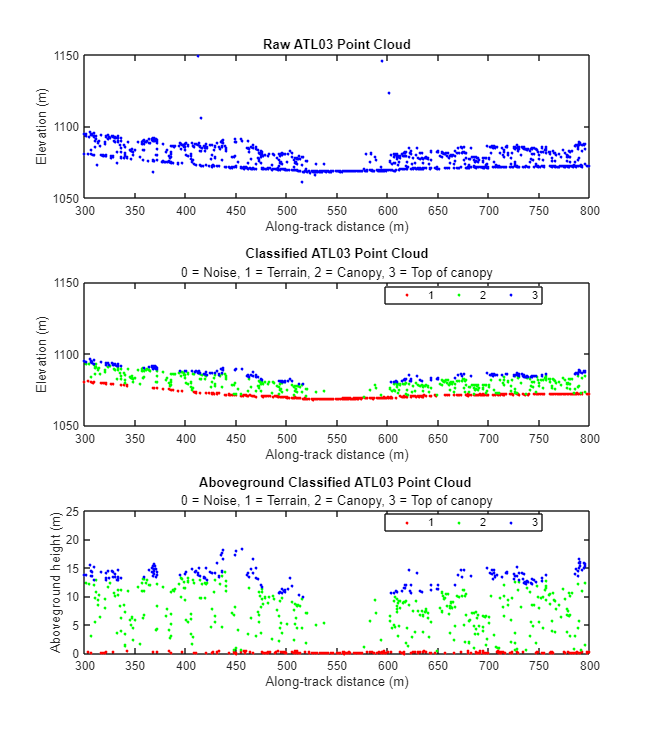

atdlim = [300,800];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.5 1]);
tiledlayout(3,1);

% plot raw point cloud directly from gt object
ax0 = nexttile;
atdplot(gt,'r',[],atdlim) % plot using default colors
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

% plot classified point cloud 
ax1 = nexttile;
atdplot(cpc,'c',[],atdlim)
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

% plot aboveground point cloud
ax2 = nexttile;
atdplot(npc,'n',[],atdlim)
box on
xlim([atdlim(1),atdlim(2)])
ylim([0,25])
linkaxes([ax0,ax1, ax2],'x')

### Writing auxilliary vector data

Auxiliary outputs such as KML or Shapefiles representing a reference ground track (rgt) or segment level polygons can be readily generated to support visualization, presentation, or validation assessments. The current implementation only supports saving outputs in WGS84 geographical coordinates.

rgt_fn = './data/gt1l_rgt.shp'; % output filepath
gt.writergt(rgt_fn) % writes the rgt as shapefile

seg_fn = './data/gt1l_seg.shp';
gt.writesegpol(seg_fn) % writes the ATL08 segment polygons as shapefile

### Saving attribute data

Attribute data, e.g.raw point clouds, can readily be saved as textfiles to facilitate further analyses. The code below saves the *pc* table retrieved in the precedding steps to a CSV file using the savetable function

pc_fn = './data/gt1l_tbl.csv';
savetable(cpc,pc_fn) % writes the classified pc

## Concluding remarks

This notebook demonstrated how to use the ATLx toolbox to work with both ATL03 and ATL08 data for land and vegetation applications including reading, visualization and exporting data. Most of the functions used in this demonstration were run with defalt parameters settings. We encourage you to check each method's documentation to see how else you can apply the toolbox to meet your requirements.